# Label Signal Attributes, Regions of Interest, and Points

Reference: https://in.mathworks.com/help/signal/ug/label-signal-attributes-regions-of-interest-and-points.html

Recordings of whale songs contain trills and moans. *Trills* sound like series of clicks. *Moans* are low-frequency cries similar to the sound made by a ship's horn. You want to look at each signal and label it to identify the whale type, the trill regions, and the moan regions. For each trill region, you also want to label a few selected signal peaks.

## Load Unlabeled Data

Start by loading a data set that includes two recordings of whale songs. The signals are called `whale1` and `whale2` and are sampled at 4 kHz. `whale1` consists of a trill followed by three moans. `whale2` consists of two moans, a trill, and another moan.

load labelwhalesignals

% To hear, type soundsc(whale1,Fs), pause(22), soundsc(whale2,Fs)

Bring the signals into **Signal Labeler**:

- Open [**Signal Labeler**](docid:signal_ref#mw_cecb4589-4122-4388-95da-2a5796c6e3e2). On the **Labeler** tab, click **Import** and select `From Workspace` in the **Members** list.

- In the dialog box, select the signals. Add time information: Select `Time` from the drop-down list and enter the sample rate `Fs`, which is measured in Hz. 

- Click **Import and Close** to import the signals and then close the dialog box. The signals appear in the **Labeled Signal Set Browser**. To plot any of the signals, you can select the check box next to its name in the browser.

## Add Signal Label Definitions

Define labels to attach to the signals. For more information about the kinds of labels you can define, see [Create or Import Signal Label Definitions](docid:signal_ug#mw_66024017-6481-4c13-bbd2-bd7664dccb54).

For the whale song signals:

- Define a categorical attribute label to store whale types. Call it `WhaleType`. The possible categories are blue whale, humpback whale, and white whale.

- Define a logical region-of-interest (ROI) label that is true for moan regions. Call it `MoanRegions`.

- Define a logical ROI label that is true for trill regions. Call it `TrillRegions`.

- Define a numeric point sublabel to capture trill peaks. Call it `TrillPeaks`. Set this label as a sublabel of the `TrillRegions` label.

To define each label, click **Add **in the **Label Definition** section on the **Labeler** tab. To define the sublabel, select the `TrillRegions` label in the **Label Definitions** browser, click **Add**, and select `Add sublabel definition`.

Enter these values in the fields in the dialog box that appears for each signal label or sublabel definition. Leave the **Default** field empty in each case.


$$$$
\kern.5in\matrix{
\matrix{\cr
  {\bf Label\;Name}_\hline&
  {\bf Label\;Type}&
  {\bf Label\; Description}&
  {\bf Data\; Type}&
  {\bf Categories}
  \cr\hline
  {\tt WhaleType}&{\tt Attribute}&{\tt Whale\;type}&{\tt categorical}
  &\left\{\matrix{{\tt blue}\cr{\tt humpback}\cr{\tt white}\cr}\right.
  \cr
  {\tt MoanRegions}&{\tt ROI}&{\tt Regions\;where\;moans\;occur}&{\tt logical}
  &{\rm ---}
  \cr
  {\tt TrillRegions}&{\tt ROI}&{\tt Regions\;where\;trills\;occur}&{\tt logical}
  &{\rm ---}
  \cr
  {\tt TrillPeaks}&{\tt Point}&{\tt Trill\;peaks}&{\tt numeric}&{\rm ---}
  \cr
}
\cr\;_\hline\;
}
$$$$


You can export the signal definitions you created to a MAT-file or to the MATLAB® Workspace by clicking **Export**. A dialog box appears that prompts you for a file name. At any point you can import signal definitions stored in a MAT-file by clicking **Import**.

## Label Signal Attributes

The songs in the data are from two blue whales. Set the `WhaleType` values for both signals: 

- Select `WhaleType` on the **Label Definitions** browser.

- Click the **Label All** button in the **Set Label Value** section.

- In the dialog box that appears, verify that both `whale1` and `whale2` are selected and that the **Value** field is set to `blue`. (If you do not specify a default value in a categorical signal label definition, **Signal Labeler** sets the label to the first category specified in the definition.)

- Click **OK**.

Set the `WhaleType` value for one signal at a time:

- Check the box next to the signal name in the **Labeled Signal Set Browser**.

- Select `WhaleType` on the **Label Definitions** browser.

- Click the **Label Attribute** button in the **Set Label Value** section. The value for `WhaleType` appears in the **Labeled Signal Set Browser**.

- Select the value for `WhaleType` from the **Value** drop-down list.

Plot the `whale1` signal by selecting the check box next to its name. Signal attributes appear both in the **Labeled Signal Set Browser** and under the time plot.

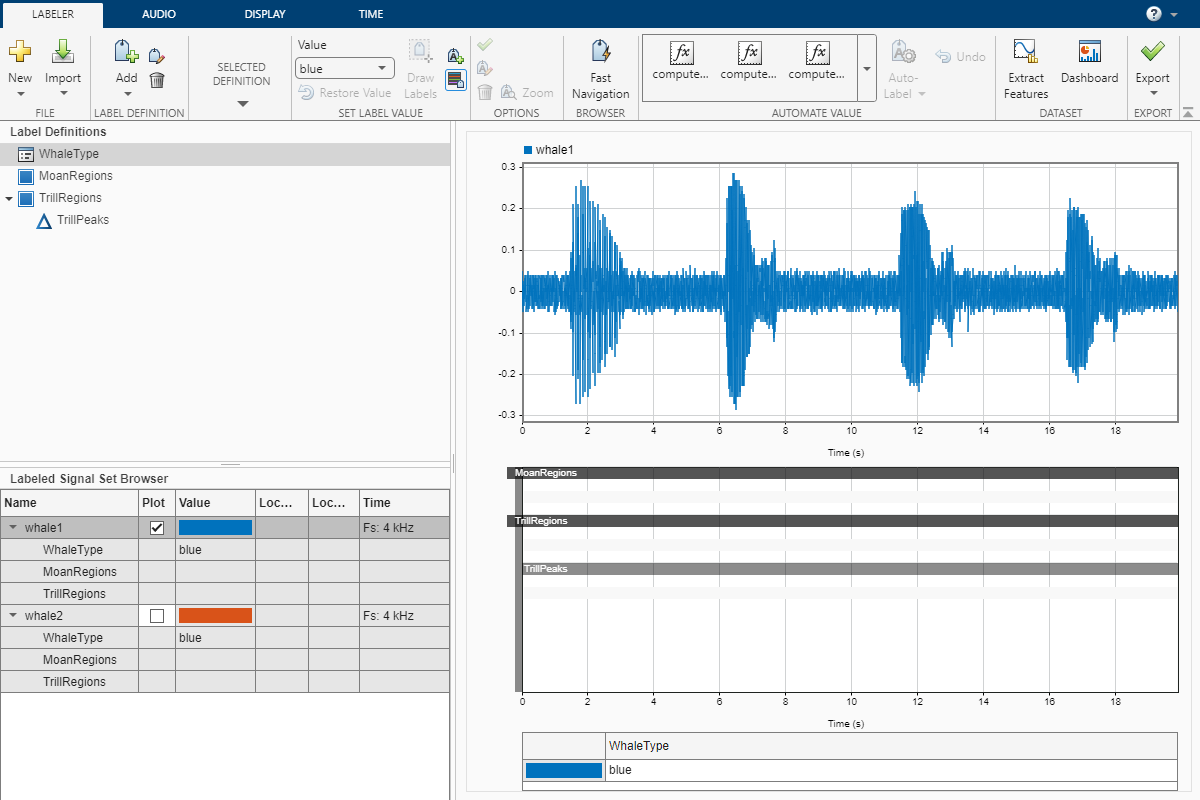

## Label Signal Regions

Visualize the whale songs and label the trill and moan regions.

- Trill regions have distinct bursts of sound punctuated by silence. `whale1` has a trill centered at about 2 seconds.

- Moan regions are sustained low-frequency wails. `whale1` has moans centered at about 7 seconds, 12 seconds, and 17 seconds.

Label the signals one at a time:

- On the **Plot** column of the **Labeled Signal Set Browser**, check the box next to the signal name to plot the signal.

- To label a moan, on the **Label Definitions** browser, select the `MoanRegions` label definition. **Draw** **Labels** is automatically activated.

- Click the time plot. A thick animated dashed line appears that expands into a shaded region when you click and drag. 

- Move and resize the active region until it encloses a moan region. For better label placement, you can go to the **Display** tab and choose a zoom action or activate the panner.

- Click the **Accept** check mark in the **Options** section of the **Labeler** tab, press **Enter**, or double-click to label the ROI. The region changes to a gradient of the signal color. If you do not specify a default value in a logical label definition, **Signal Labeler** sets the label to `true`.

- Repeat the procedure for the other two moans.

- To label a trill, on the **Label Definitions** browser, select the `TrillRegions` label definition. Label the trill region using steps 3 and 4.

- Before labeling the second signal, remove the first signal from the plot by clearing the check box next to its name in the **Labeled Signal Set Browser**. If you have the two signals plotted when you label a region or point, **Signal Labeler** associates the label with both signals.

Plot the two signals. The label viewer axes show the locations and widths of the regions of interest. They also show the value assigned to each region.

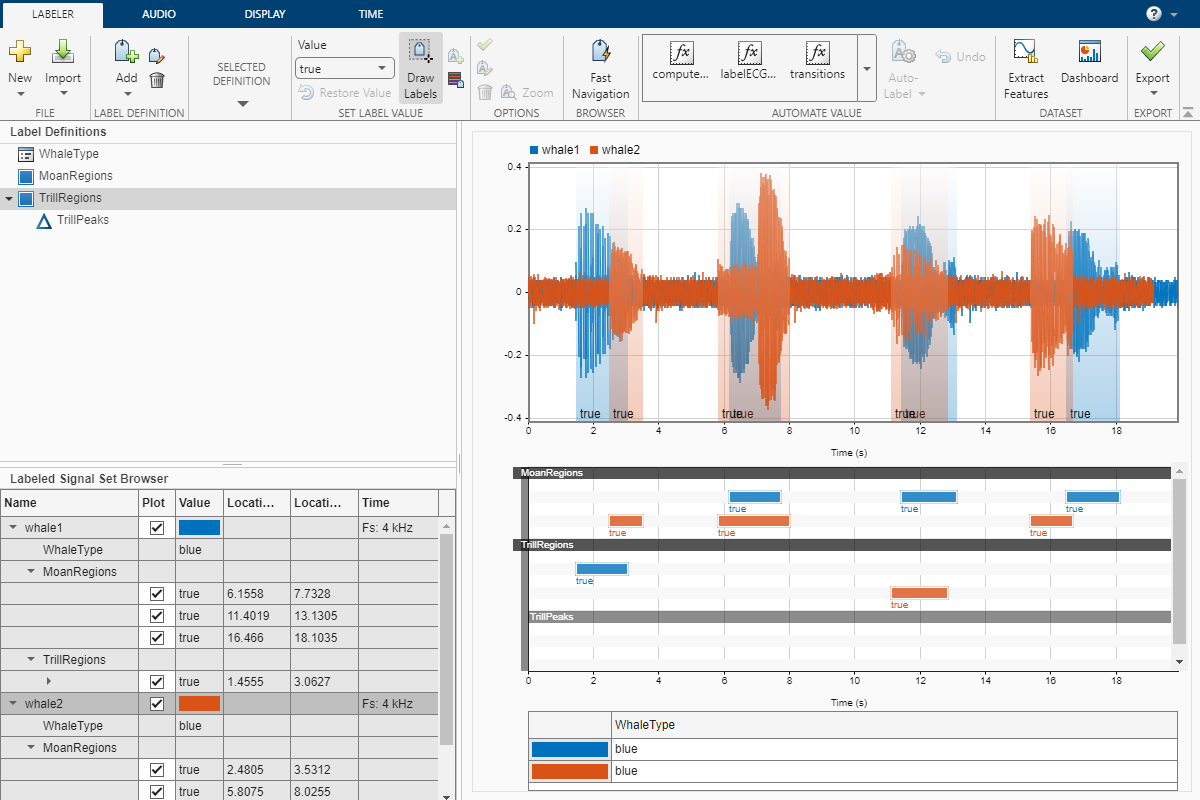

## Label Signal Points

Trill regions have distinct peaks that correspond to bursts of sound. Label three peaks in each trill region. Because trill peaks are sublabels, each one must be associated with a particular `TrillRegions` label.

Label the signals one at a time:

- On the **Plot** column of the **Labeled Signal Set Browser**, check the box next to the signal name to plot the signal. Also check the box corresponding to the trill region whose peaks you want to label.

- On the **Label Definitions** browser, select `TrillPeaks`. **Draw Labels** is automatically selected.

- On the toolstrip, under **Value**, enter `1`, corresponding to the first peak.

- On the **Labeled Signal Set Browser**, select the trill region.

- Click the point on the time plot. The trill region is framed by a solid line, and an animated dashed (active) line appears for the point being labeled.

- Move the active line until it crosses the signal at a peak of your choice. For better label placement, you can go to the **Display** tab and choose a zoom action or activate the panner.

- Click the check mark in the **Options** section of the **Labeler** tab, press **Enter**, or double-click to label the peak. The dashed line changes to a solid line of the same color as the signal.

- Repeat for two more peaks, entering `2` and `3` under **Value** to identify them.

- Before labeling trill peaks for the second signal, remove the first signal from the plot by clearing the check box next to its name in the **Labeled Signal Set Browser**.

The label viewer axes show the locations of the points of interest and the value assigned to each point.

Plot the two signals to see a summary of their labels in the **Label Viewer**. Expand the labeled signal set hierarchy in the **Labeled Signal Set Browser** to see details for all the labels. (To expand the hierarchy, right-click on the browser header and select `Expand All`.) For each signal, plot the first moan region and the third trill peak that you labeled.

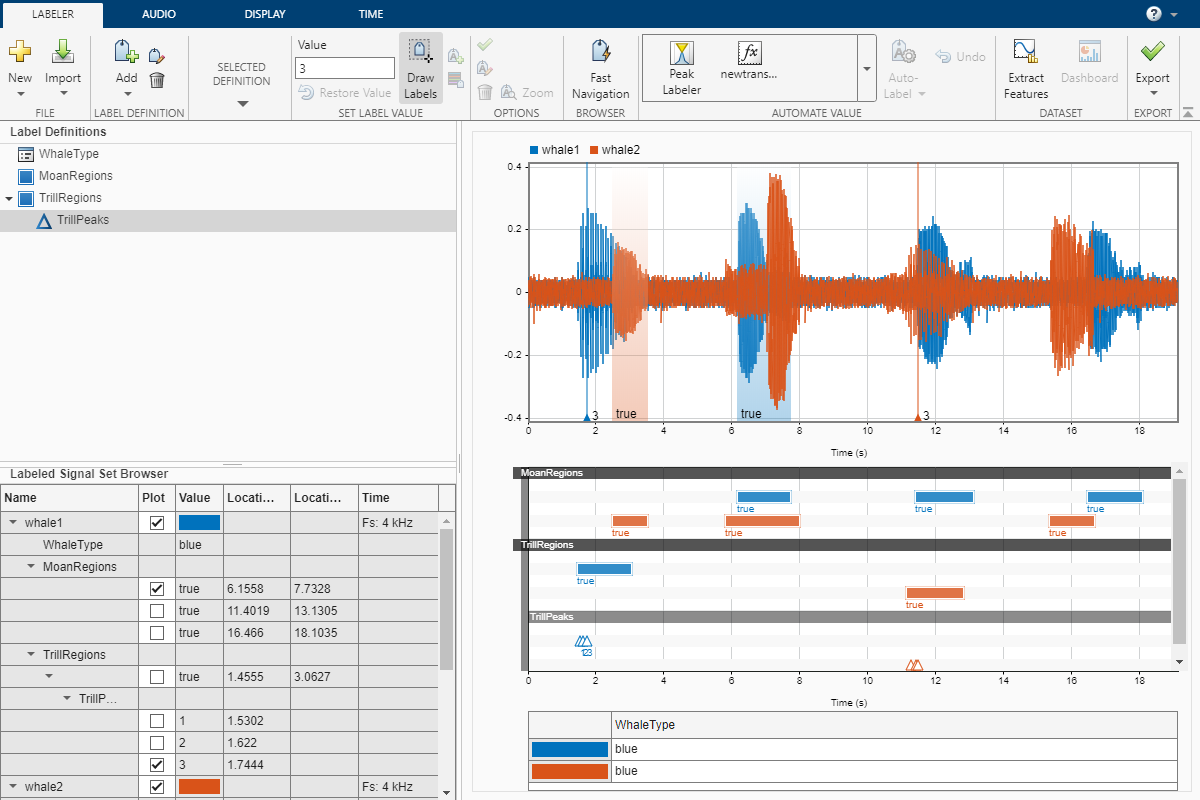

## Change Signal Line Color

To change the line color of a signal, right-click the member name and select `Change Color`, or click the color value in the **Labeled Signal Set Browser**. Choose a standard or custom color from the **Pick a Color** dialog box.

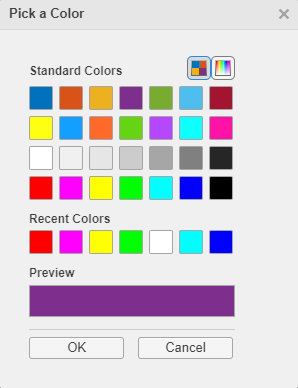

## Edit Signal Label Values

At any point, you can edit any signal label using the **Labeled Signal Set Browser**, the time plot, or the label viewer. For more information, see [Edit Labels](docid:signal_ug#mw_9f4cd511-11c3-4487-952a-c5c78b7fae68).

## Export Labeled Signal Set

Export the labeled signals as a new `labeledSignalSet` object. Click the **Export** button on the **Labeler** tab of the toolstrip. You can export the labeled signal set to the MATLAB Workspace or to a MAT-file. For this example, choose a MAT-file. In the dialog box that appears, give the name W`hale_Songs.mat` to the labeled signal set, add an optional short description, and click **Export**. See [Signal Labeler Import and Export Behavior](docid:signal_ug#mw_1bc1b814-0eb6-41ea-b4ee-b741a699e3c5) for more information on how **Signal Labeler** exports labeled signal sets.

*Copyright 2018 The MathWorks, Inc.*